%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
noise_power = calculate_noise_power(f_sampling, 1e-3);
noise = generate_thermal_noise(t, noise_power);

f_0 = f_a;
f_0_original = f_a_original;
Q_resonator_original = 1e6;
Q_resonator = Q_resonator_original / heterodyning_ratio;
band_width = f_0 / Q_resonator

band_width = 483.5590

band = [f_0-band_width/2, f_0+band_width/2];
limiting_band = [f_0-band_width, f_0+band_width];

%% finish generation
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_resonator_original);

tau_iwave = 8e-5;
f_guess = f_0;

R = @(Q, df, f_res_o) 1 ./ (1 + 4*Q^2 * df.^2 ./ f_res_o.^2 );

state_res = resonator_setup();

signal_res = zeros(size(t));
signal_R = zeros(size(t));
f_0_current = f_0

f_0_current = 2.4178e+07

for i = 1 : length(t)
    resonator_input = signal(i);
    [state_res, resonator_output] = resonator_step2(state_res, resonator_input, f_0_current, band_width, f_sampling);
    signal_res(i) = resonator_output;

    signal_R(i) = signal(i) * sqrt(R(Q_resonator_original, f_axion(i) - f_0_current, f_0_current + heterodyning_shift));
end

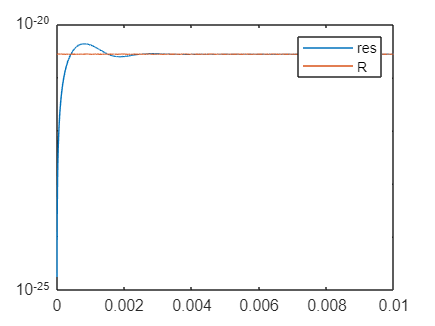

powers_res = zeros(1, floor(length(t)/1000));
powers_R = zeros(1, floor(length(t)/1000));
j = 0;
for i = 1 : 1000 : length(t) - 1000
    j = j+1;
    powers_res(j) = bandpower(signal_res(i:i+1000));
    powers_R(j) = bandpower(signal_R(i:i+1000));
end

figure
plot(t_small(1:end-1), powers_res)
hold on
plot(t_small(1:end-1), powers_R)
set(gca, 'yscale','log')
legend('res', 'R')